density = 10

averagespeed = 0.0161

S = 0.0028

density = 20

averagespeed = 0.0153

S = 0.0086

density = 30

averagespeed = 0.0236

S = 0.0086

density = 40

averagespeed = 0.0350

S = 0.0095

density = 50

averagespeed = 0.0377

S = 0.0057

density = 60

averagespeed = 0.0422

S = 0.0171

density = 70

averagespeed = 0.0504

S = 0.0147

density = 80

averagespeed = 0.0575

S = 0.0233

density = 90

averagespeed = 0.0497

S = 0.0139

density = 100

averagespeed = 0.0723

S = 0.0222

density = 110

averagespeed = 0.0797

S = 0.0411

density = 120

averagespeed = 0.0765

S = 0.0183

density = 130

averagespeed = 0.0986

S = 0.0249

density = 140

averagespeed = 0.0996

S = 0.0259

density = 150

averagespeed = 0.1034

S = 0.0267

density = 160

averagespeed = 0.1150

S = 0.0262

density = 170

averagespeed = 0.1250

S = 0.0181

density = 180

averagespeed = 0.1235

S = 0.0226

density = 190

averagespeed = 0.1222

S = 0.0271

density = 200

averagespeed = 0.1489

S = 0.0239

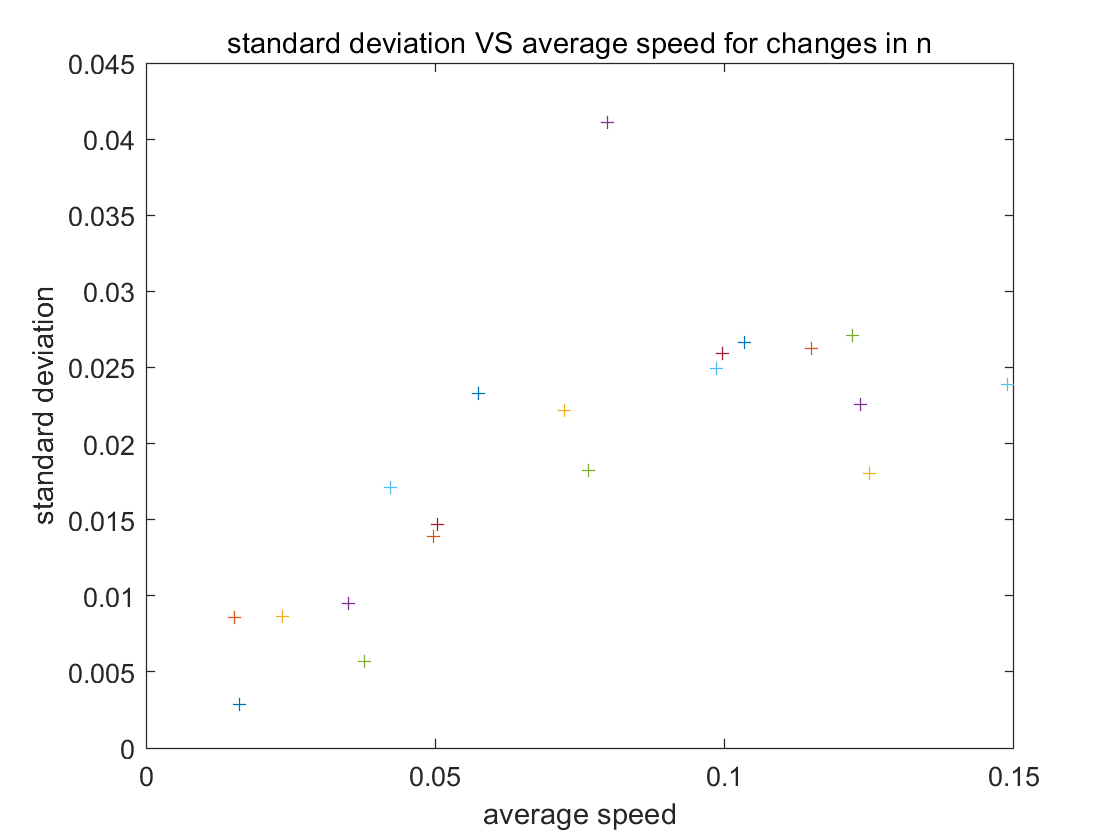

clc;
clear;
for count=1:20
Road_length  =1;
car_number   = count*10;
acceleration = 0.0019;
deceleration = -0.0049;
density = car_number/Road_length
%initial speed
u = 0.5;
%time limitis
time =200;
%limit speed
lim = 1;

%repeat loop
for l=1:10
%initial position of car
J = 1:car_number;
A = rand(1,car_number).*Road_length;
x(J,1) =sort(A);
v(J,1)=u;
%minimum distance between cars
x0 = Road_length/car_number;
num = car_number-1;
delT = 0.1;
k = time / delT;
%
average(1) = 0;
t(1) = 0;

for T=2:k
    for J=1:car_number
        if J == car_number
            dis(J,T) = x(1,T-1)-x(J,T-1);
        else
            dis(J,T) = x(J+1,T-1)-x(J,T-1);
        end
        if dis(J,T)<0
            dis(J,T) = Road_length+dis(J,T);
        end
        if dis(J,T) > x0/2
           v(J,T)=v(J,T-1) + acceleration * delT;
        elseif dis(J,T) <= v(J,T-1)
            dis(J,T)=0;
            v(J,T)=0;
        else
           v(J,T)=v(J,T-1)+ deceleration * delT;
        end
        if v(J,T)<0
            v(J,T)=0;
        end
        if v(J,T)>lim
            v(J,T)=lim;
        end
        x(J,T)=x(J,T-1)+v(J,T)*delT;
        if x(J,T) > Road_length
           x(J,T)=x(J,T)- Road_length;
        end
    end
      max_speed(T) = max(v(J,T));
      min_speed(T) = min(v(J,T));
      average(T) = sum(v(:,T)) / car_number;
      t(T) = t(T-1) + delT;
end
t(T) = t(T);
x(J,T)=x(J,T);
v(J,T)=v(J,T);
average(T) = average(T);
k_1 = floor(k/3);
d_av = average(1,(k_1):k);
m(l) = mean(d_av);
end
averagespeed = mean(m) 
S=std(m)
plot(averagespeed,S,"+","MarkerSize",5)
title("standard deviation VS average speed for changes in n")
xlabel('average speed')
ylabel('standard deviation')
hold on
end